# Vector Part 1:

## Vector and Basic Operation of Vector

### Code Exercise (02_01)

> Three methods for creating vectors.

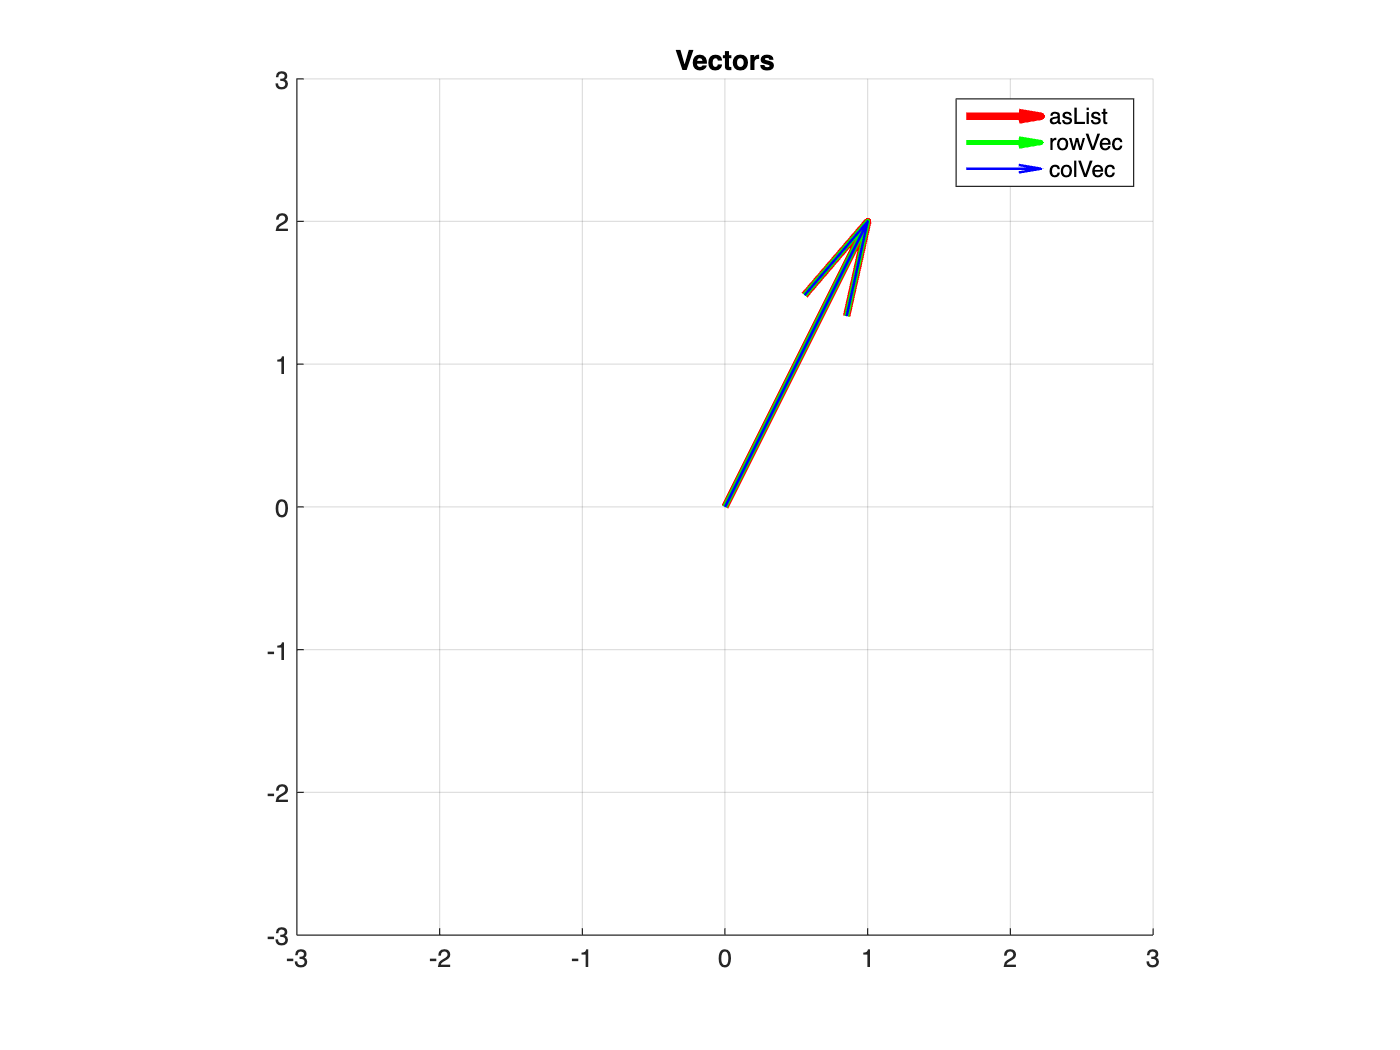

clear; close all; clc;

% Creating a vector as a MATLAB list
asList = [1, 2];

% Creating a row vector
rowVec = [1, 2]; % row

% Creating a column vector
colVec = [1; 2]; % column

% Plotting the vectors using quiver
figure;
hold on;

% To prevent overlap, ther is a 0.1 offset in the starting points of the vectors.
quiver(0, 0, asList(1), asList(2), 'r', 'LineWidth', 3, AutoScale='off', MaxHeadSize=1);
quiver(0, 0, rowVec(1), rowVec(2), 'g', LineWidth=2, AutoScale='off', MaxHeadSize=1);
quiver(0, 0, colVec(1), colVec(2), 'b', LineWidth=1, AutoScale='off', MaxHeadSize=1);

% Set axes properties
axis equal;
xlim([-3, 3]);
ylim([-3, 3]);

% Show grid
grid on;

% Title for the visualization
title('Vectors');

% Legend for vectors
legend('asList', 'rowVec', 'colVec');

### Code Exercise (02_02)

> Generate vectors with different reference points.

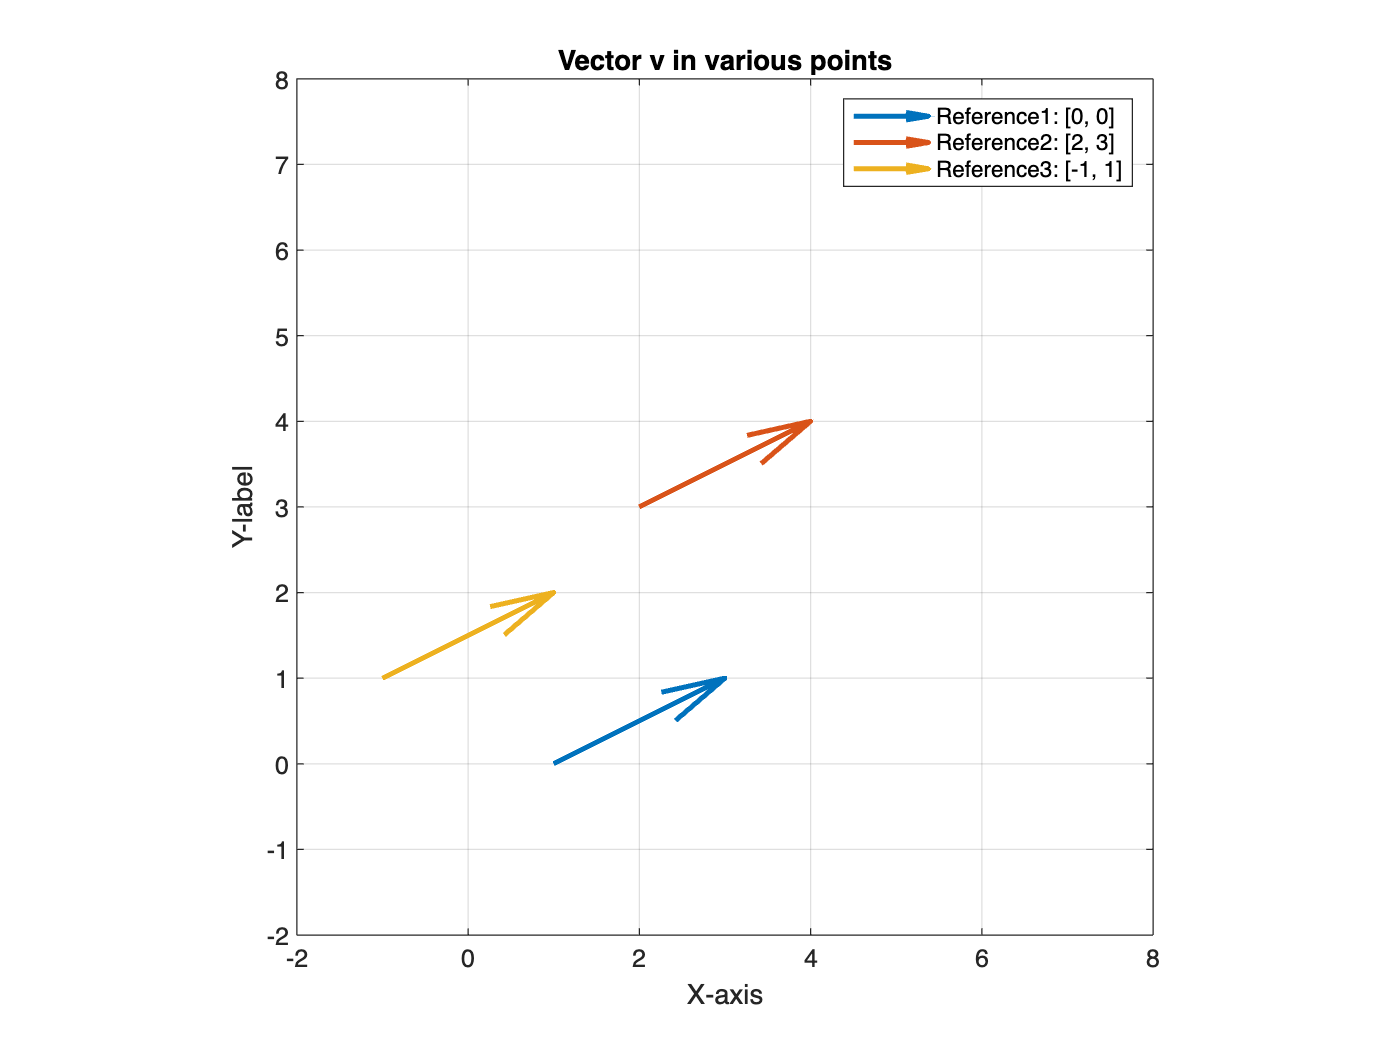

close all; clear; clc;

% Define the vector
v = [2, 1];


% Define three different reference points
reference_points = [1, 0; 2, 3; -1, 1];

% Create a figure
figure;

% Plot the vector with each reference point
for i = 1:size(reference_points, 1)
    quiver(reference_points(i, 1), reference_points(i, 2), v(1), v(2), ...
        LineWidth=2, AutoScale="off", MaxHeadSize=2);
    hold on;
end

% Set axes properties
axis equal;
xlim([-2, 8]);
ylim([-2, 8]);

% Show grid
grid on;

% Title for the visualizstion
title('Vector v in various points');

% Axes labels
xlabel('X-axis');
ylabel('Y-label');

% Legend for vectors with different reference points
legend('Reference1: [0, 0]', 'Reference2: [2, 3]', 'Reference3: [-1, 1]');

### Code Exercise (02_03)

> Addition between two vector.

close all; clear; clc;

%% Adding Vectors

% Using 2D vectors here instead of 3D vectors in the book to facilitate
% visualization
v = [1, 2];
w = [4, -6];
vPlusW = v + w;

% print out all three vectors
disp('v:');

v:


disp(v);

     1     2



disp('w:');

w:


disp(w);

     4    -6



disp('vPlusW:');

vPlusW:


disp(vPlusW);

     5    -4



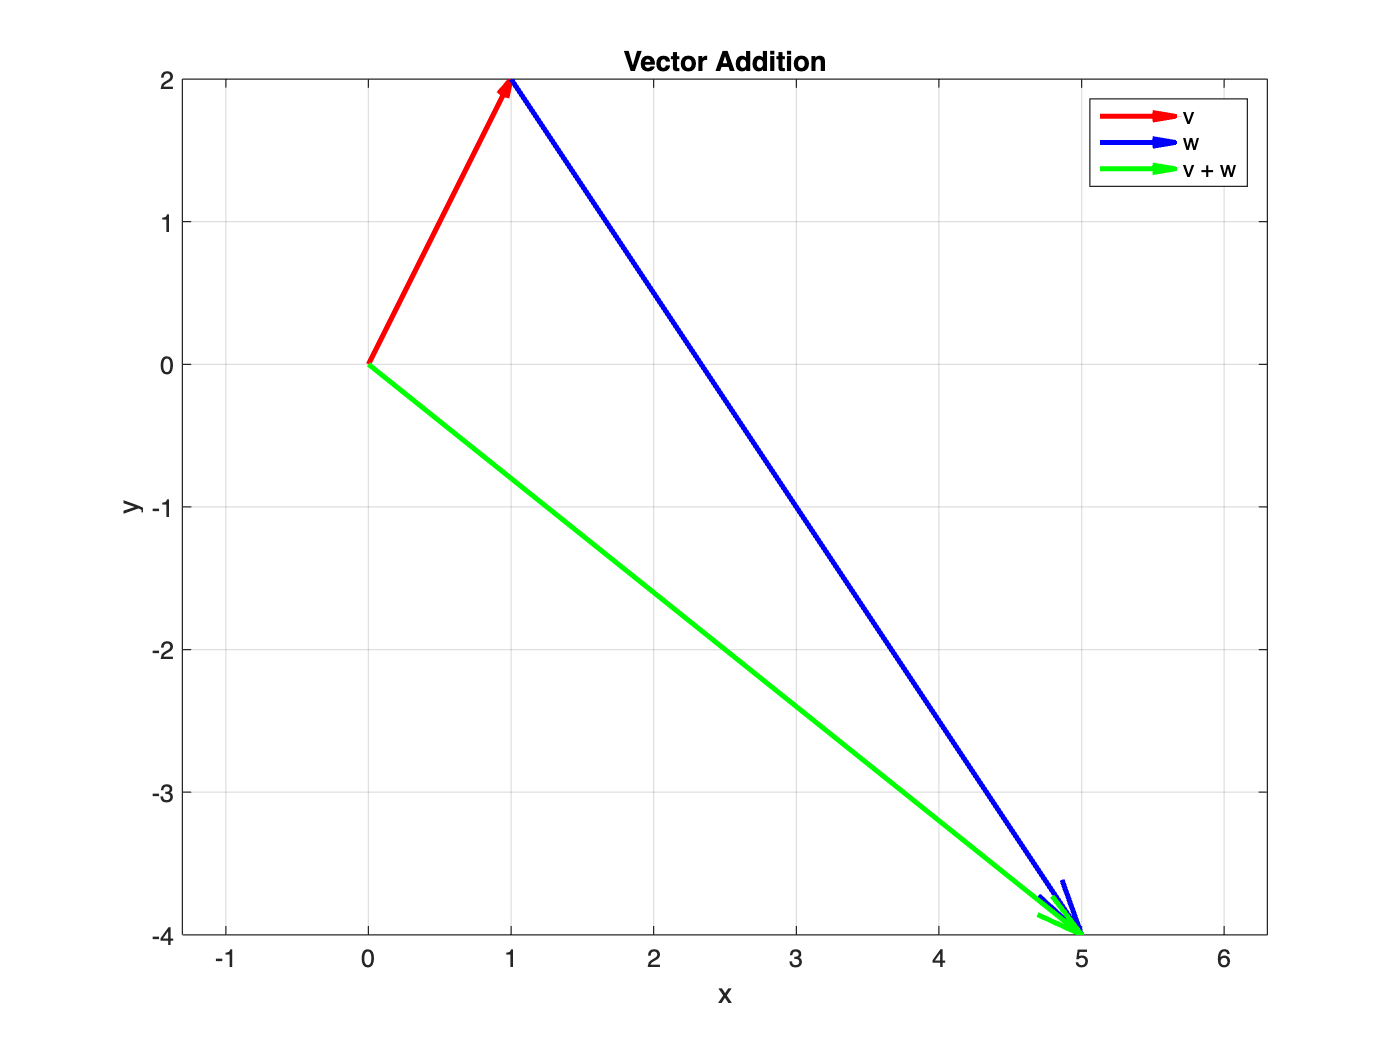


% Plot vectors
quiver(0, 0, v(1), v(2), 0, 'r', LineWidth=2);
hold on;
quiver(v(1), v(2), w(1), w(2), 0, 'b', LineWidth=2);
quiver(0, 0, vPlusW(1), vPlusW(2), 0, 'g', LineWidth=2);
hold off;

axis equal;
xlabel('x');
ylabel('y');
title('Vector Addition');
legend('v', 'w', 'v + w');
grid on;

### Code Exercise (02_04)

> Broadcasting - see diagonal element.

close all; clear; clc;

% column vector and row vector
column_vector = [1; 2; 3];
row_vector = [4 5 6];

% Using 2D vectors here instead of 3D vectors in the book to facilitate
% visualization
sum_result = column_vector + row_vector;
differece_result = column_vector - row_vector;

% print out all three vectors
disp('addition:');

addition:


disp(sum_result);

     5     6     7
     6     7     8
     7     8     9



disp('subtraction:');

subtraction:


disp(differece_result);

    -3    -4    -5
    -2    -3    -4
    -1    -2    -3



### Vector addition

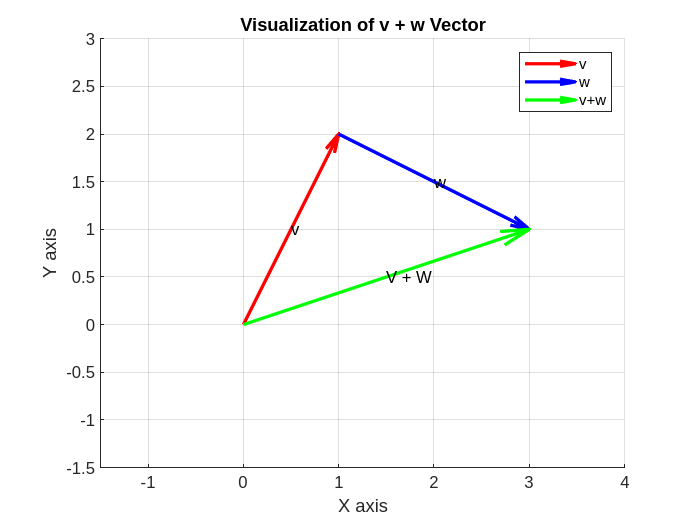

clc; clear; close all;

v = [1 2];
w = [2 -1];
vPlusW = v + w;
vMinusW = v - w;

figure;
hold on;

quiver(0, 0, v(1), v(2), 0, 'r', LineWidth=2, MaxHeadSize=0.3, DisplayName='v');
quiver(v(1), v(2), w(1), w(2),0, 'b', LineWidth=2, MaxHeadSize=0.3, DisplayName='w');
quiver(0, 0, vPlusW(1), vPlusW(2),0, 'g', LineWidth=2, MaxHeadSize=0.3, DisplayName='v+w');

grid on;
axis equal;
xlabel('X axis');
ylabel('Y axis');

title('Visualization of v + w Vector');
%legend('v', 'w', 'v + w');
legend("show");
xlim([-1.5 4]);
ylim([-1.5, 3]);

text(v(1)/2, v(2)/2, 'v');
text(v(1) + w(1)/2, v(2) + w(2)/2, 'w');
text(vPlusW(1)/2, vPlusW(2)/2, 'V + W');
hold off;

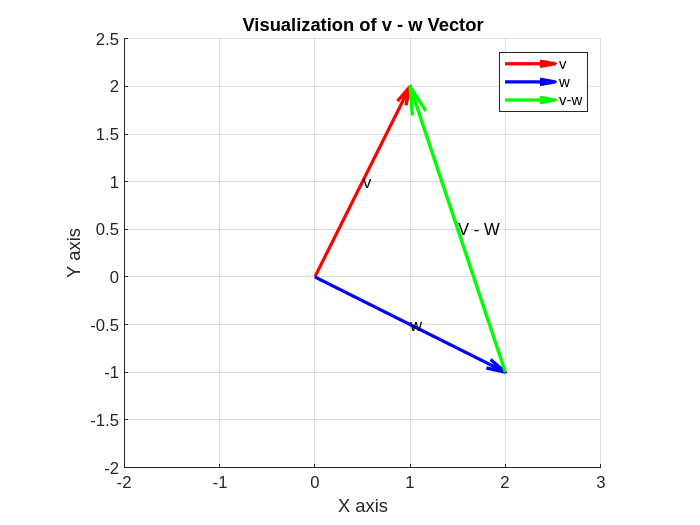


figure;
hold on;

quiver(0, 0, v(1), v(2), 0, 'r', LineWidth=2, MaxHeadSize=0.3, DisplayName='v');
quiver(0, 0, w(1), w(2),0, 'b', LineWidth=2, MaxHeadSize=0.3, DisplayName='w');
quiver(w(1), w(2), vMinusW(1), vMinusW(2),0, 'g', LineWidth=2, MaxHeadSize=0.3, DisplayName='v-w');

title('Visualization of v - w Vector');
axis equal;
grid on;
xlim([-2, 3]);
ylim([-2, 2.5]);

xlabel('X axis');
ylabel('Y axis');

legend("show");


text(v(1)/2, v(2)/2, 'v');
text(w(1)/2, w(2)/2, 'w');
text(w(1) + vMinusW(1)/2, w(2) + vMinusW(2)/2, 'V - W');

hold off

### Code Exercise (02_05)

> multiplication between scalar-vector

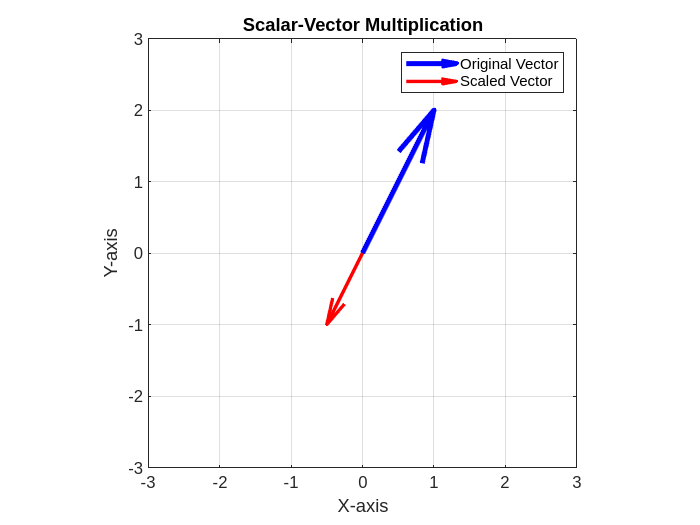

clc; clear; close all;

% Define the vector
v = [1, 2];

% Define the scalar
s = -1/2;

% Compute the scaled vector
scaled_v = s * v;

% Created a figure
figure;

% Plot the original vector
quiver(0, 0, v(1), v(2), 'b', LineWidth=3, AutoScale='off', MaxHeadSize=2, DisplayName='Original Vector');
hold on;

% Plot the scaled vector
quiver(0, 0, scaled_v(1), scaled_v(2), 'r', LineWidth=2, AutoScale='off', MaxHeadSize=2, DisplayName='Scaled Vector');

% Set axes properties
axis equal;
xlim([-3, 3]);
ylim([-3, 3]);

% Show grid
grid on;

% Title for the visualization
title('Scalar-Vector Multiplication');

% Axes labels
xlabel('X-axis');
ylabel('Y-axis');

% Legend for vectors
%legend('Original Vector', 'Scaled Vector')
legend("show");

### Norm

clc; clear; close all;

u = rand(4, 1);
v = rand(4, 1);
uPlusV = u + v;

n1 = norm(u, 2);
n2 = norm(v, 2);
disp(n1 + n2);

    2.3279




disp(norm(uPlusV, 2));

    2.1772



### Code Exercise (02_07)

> L1 norm(Manhattan norm)

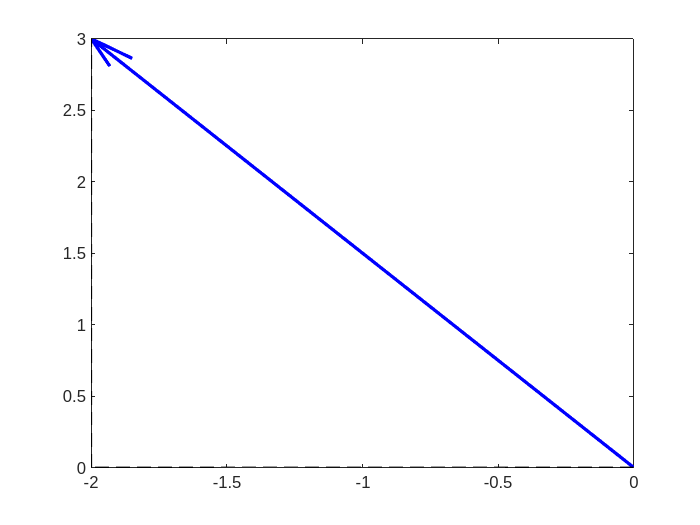

clc; clear; close all;

% Define vector
v = [-2, 3];

% Calculate L1 norm
l1_norm = norm(v, 1);

% Display vector from the origin
quiver(0, 0, v(1), v(2), 'b', LineWidth=2, AutoScale='off', DisplayName='Vector V');
hold on;

% Add lines representing movement along each axis to visualize Manhattan
% distance
plot([0, v(1)], [0, 0], '--k', LineWidth=1);
plot([v(1), v(1)], [0, v(2)], '--k', LineWidth=1);